%	Initialise script
Proj = currentProject;
cd(fullfile(Proj.RootFolder, "TicTacToe"));

%	Create environment
NumObs = 3^9;		%	Number of observation states (Pl 1, Pl 2 or empty in each grid position)
NumAct = 9;			%	Number of actions (3x3 grid)

OI = rlFiniteSetSpec(1:NumObs);		%	Observation Info
OI.Name = "Tic-Tac-Toe Observation States";

AI = rlFiniteSetSpec(1:NumAct);		%	Action Info
OI.Name = "Tic-Tac-Toe Actions";

%	Create QTable
%		Note that not all states are possible (e.g. all one counter or some multiple
%		3 in a row)
qTable = rlTable(OI, AI);
qRepresentation = rlQValueRepresentation(qTable, OI, AI);
qRepresentation.Options.LearnRate = .5;

%	Create Agent Options
agentOpts = rlQAgentOptions;
agentOpts.EpsilonGreedyExploration.Epsilon = .9;
agentOpts.EpsilonGreedyExploration.EpsilonDecay = 1e-3;
agentOpts.EpsilonGreedyExploration.EpsilonMin = 1e-3;
qAgent = rlQAgent(qRepresentation, agentOpts);

%	Set training options
trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 10;
trainOpts.MaxEpisodes= 1e5;
trainOpts.StopTrainingCriteria = "EpisodeCount";
trainOpts.StopTrainingValue = trainOpts.MaxEpisodes;
trainOpts.ScoreAveragingWindowLength = 10;
trainOpts.Plots = "None";

%	Train the agent
rng(0);
Reset(trainOpts.MaxEpisodes);
env = rlFunctionEnv(OI, AI, @Step, @()Reset);
trainingStats = train(qAgent, env, trainOpts);
multiWaitbar('Training', 'Close');
trainingStats.Information.ElapsedTime

ans = '2769.4 sec'

% return

## Compare AI v Bot

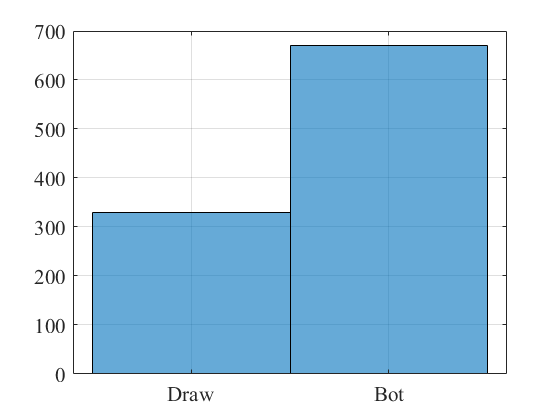

% load("TrainingData.mat", "qAgent");
obj = TicTacToe;
w = [];
for n=1:1000
	obj.Reset;
	% 	P_AI = randi(2);
	P_AI = 2;
	W = 0;
	while ~W
		if obj.CurrentPlayer~=P_AI
			obj.Choose("Bot", true);
		else
			obj.Choose("Agent", qAgent);
		end
		[W, Res] = obj.CheckWinner;
	end
	w(n) = (W<=0)*(-1-W) + (W>0)*(2 - (W==P_AI));
end
histogram(w)
grid on;
set(gca, "XTick", -1:2, "XTickLabel", ["Illegal", "Draw", "AI", "Bot"])

## Compare AI v AI

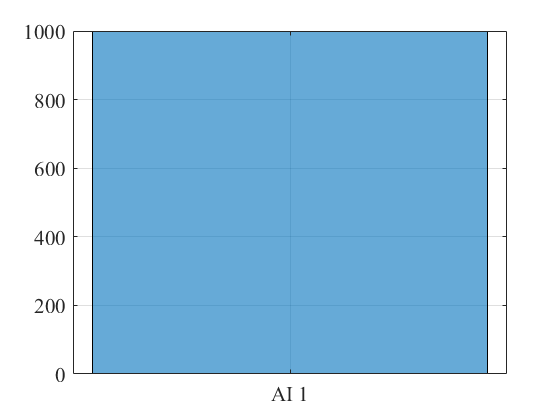

% load("TrainingData.mat", "qAgent");
obj = TicTacToe;
w = [];
for n=1:1000
	obj.Reset;
	W = 0;
	while ~W
		obj.Choose("Agent", qAgent);
		[W, Res] = obj.CheckWinner;
	end
	w(n) = (W>0).*W;
end
histogram(w)
grid on;
set(gca, "XTick", 0:2, "XTickLabel", ["Draw", "AI 1", "AI 2"])

## Reset function

Used to generate initial state and logged signals (Data)

function [InitState, Data] = Reset(varargin)
persistent N count
if nargin
	if isnumeric(varargin{1})
		N = varargin{1};
		multiWaitbar('Training', 'Reset');
	else
		try
			multiWaitbar('Training', 'Close');
		end
		N = nan;
	end
	count = 0;
	return;
end

Algorithms = ["Random", "Bot"];

Data = struct( ...
	"Obj", TicTacToe, ...
	"Player", randi(2), ...
	"Algorithm", randsample(Algorithms, 1), ...
	"Options", {{}});

switch Data.Algorithm
	case "Bot"
		Data.Options = {logical(randi(2)-1)};
end

if Data.Player==2
	Data.Obj.Choose(Data.Algorithm, Data.Options{:});
end

InitState = Data.Obj.GetState;
count = count + 1;
if isfinite(N) && ~mod(count, 100)
	multiWaitbar('Training', 'Increment', 100/N);
end
end


## Step Function

Used to generate the next step in the algorithm

%	Step by applying the action to the game board
function [State, Reward, IsDone, Data] = Step(Action, Data)
Rewards = struct( ...
	"Win", 20, ...
	"Draw", -5, ...
	"Lose", -20, ...
	"Illegal", -inf);

%	If currentplayer not changed, then return illegal move
if Data.Obj.Grid(Action)
	Result = nan;
else
	%	Attempt to insert counter in grid index Action
	[Row, Col] = ind2sub([3 3], Action);
	Data.Obj.Insert(Row, Col);
	Result = Data.Obj.CheckWinner;
	if abs(Result)~=1
		Data.Obj.Choose(Data.Algorithm, Data.Options{:});
		Result = Data.Obj.CheckWinner;
	end
end

switch Result
	case Data.Player
		Reward = Rewards.Win;
	case 3-Data.Player
		Reward = Rewards.Lose;
	case -1
		Reward = Rewards.Draw;
	case 0
		Reward = sum(Data.Obj.CalculateScores.^3) * (3-2*Data.Player)/10;
	otherwise
		Reward = Rewards.Illegal;
end
if ~isfinite(Result) || logical(Result)
	IsDone = true;
else
	IsDone = false;
end

State = Data.Obj.GetState;
end
